%24/02/2024 Manual Obstacle avoidance demo
P1 = [100, 0];
P2 = [0, 0];
P3 = [0, 100];
P4 = P3;
P5 = P4;
t1 = 0.01;
t2 = 0.02;
t3 = 0.03;
t4 = 0.04;
t5 = 40;
t6 = 59.97;
t7 = 59.98;
t8 = 59.99;
t9 = 60;
validtmin = t4;
validtmax = t6;
tmin = 0;
tmax = 60;
step = 0.01;
stackx = [];
stacky = [];
for t = tmin:step:tmax
    if (t1<=t)
        if (t<t2)
            N1k1 = 1;
        else
            N1k1 = 0;
        end
    else
        N1k1 = 0;
    end
    if (t2<=t)
        if (t<t3)
            N2k1 = 1;
        else
            N2k1 = 0;
        end
    else
        N2k1 = 0;
    end
    if (t3<=t)
        if (t<t4)
            N3k1 = 1;
        else
            N3k1= 0;
        end
    else
        N3k1 = 0;
    end
    if (t4<=t)
        if (t<t5)
            N4k1 = 1;
        else
            N4k1 = 0;
        end
    else
        N4k1 = 0;
    end
    if (t5<=t)
        if (t<t6)
            N5k1 = 1;
        else
            N5k1 = 0;
        end
    else
        N5k1 = 0;
    end
    if (t6<=t)
        if (t<t7)
            N6k1 = 1;
        else
            N6k1 = 0;
        end
    else
        N6k1 = 0;
    end
    if (t7<=t)
        if (t<t8)
            N7k1 = 1;
        else
            N7k1 = 0;
        end
    else
        N7k1 = 0;
    end
    if (t8<=t)
        if (t<t9)
            N8k1 = 1;
        else
            N8k1 = 0;
        end
    else
        N8k1 = 0;
    end

    N1k2 = ((t-t1)/(t2-t1))*N1k1 + ((t3-t)/(t3-t2))*N2k1;
    N2k2 = ((t-t2)/(t3-t2))*N2k1 + ((t4-t)/(t4-t3))*N3k1;
    N3k2 = ((t-t3)/(t4-t3))*N3k1 + ((t5-t)/(t5-t4))*N4k1;
    N4k2 = ((t-t4)/(t5-t4))*N4k1 + ((t6-t)/(t6-t5))*N5k1;
    N5k2 = ((t-t5)/(t6-t5))*N5k1 + ((t7-t)/(t7-t6))*N6k1;
    N6k2 = ((t-t6)/(t7-t6))*N6k1 + ((t8-t)/(t8-t7))*N7k1;
    N7k2 = ((t-t7)/(t8-t7))*N7k1 + ((t9-t)/(t9-t8))*N8k1;

    N1k3 = ((t-t1)/(t3-t1))*N1k2 + ((t4-t)/(t4-t2))*N2k2;
    N2k3 = ((t-t2)/(t4-t2))*N2k2 + ((t5-t)/(t5-t3))*N3k2;
    N3k3 = ((t-t3)/(t5-t3))*N3k2 + ((t6-t)/(t6-t4))*N4k2;
    N4k3 = ((t-t4)/(t6-t4))*N4k2 + ((t7-t)/(t7-t5))*N5k2;
    N5k3 = ((t-t5)/(t7-t5))*N5k2 + ((t8-t)/(t8-t6))*N6k2;
    N6k3 = ((t-t6)/(t8-t6))*N6k2 + ((t9-t)/(t9-t7))*N7k2;

    N1k4 = ((t-t1)/(t4-t1))*N1k3 + ((t5-t)/(t5-t2))*N2k3;
    N2k4 = ((t-t2)/(t5-t2))*N2k3 + ((t6-t)/(t6-t3))*N3k3;
    N3k4 = ((t-t3)/(t6-t3))*N3k3 + ((t7-t)/(t7-t4))*N4k3;
    N4k4 = ((t-t4)/(t7-t4))*N4k3 + ((t8-t)/(t8-t5))*N5k3;
    N5k4 = ((t-t5)/(t8-t5))*N5k3 + ((t9-t)/(t9-t6))*N6k3;

    SumNPx = N1k4*P1(1,1) + N2k4*P2(1,1) + N3k4*P3(1,1) + N4k4*P4(1,1) + N5k4*P5(1,1);
    SumNPy = N1k4*P1(1,2) + N2k4*P2(1,2) + N3k4*P3(1,2) + N4k4*P4(1,2) + N5k4*P5(1,2);

    if t >= validtmin
        if t<=validtmax
            stackx = [stackx; SumNPx];
            stacky = [stacky; SumNPy];
        end
    end
end

CP = [P1; P2; P3]

CP =    100     0
     0     0
     0   100


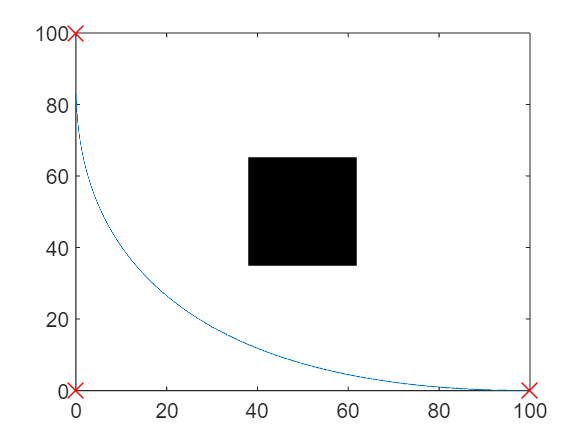

CPx = [P1(1,1), P2(1,1), P3(1,1)];
CPy = [P1(1,2), P2(1,2), P3(1,2)];
plot(stackx, stacky)
hold on
scatter(CPx, CPy, 100, "red", "X")
scatter(50, 50, 4000, "black", "square", "filled")
hold off

knotV = [t1, t2, t3, t4, t5, t6, t7, t8, t9]

knotV =     0.0100    0.0200    0.0300    0.0400   40.0000   59.9700   59.9800   59.9900   60.0000
